clearvars;
addpath('kwave/');

In order to run the k-wave simulation a source signal needs to be defined.

This source signal is given by:

source.p = source_mag * sin(2 * pi * source_freq * kgrid.t_array);

In the following we will study what effect the source_mag has on the simulation as well as other factors in order to get a better understanding of the simulations working and to know how the source strength of our own simulation has to be defined to comply with the kwave simulation.

### Initial parameter

s_mag = 1; %signal magnitude [Pa]
f = 100; %frequency [Hz]
density = 1.125; %density distribution [kg/m^3]
spacing = 1; %distance between each grid point [m]
Nt = 1000; %number of time steps
dt = 0.0001; %size of time steps [s]

### Receiver position changes

We change the position of the receiver and study the pressure signals amplitude at the different positions. The source is located at the grid center [0,0].

n = 10; % number of samples
amp = zeros(1,n+1); % Outpur pressure amplitude
for i=0:n
    p_receiver = [0 i];
    [p,t,prefix,scale] = kwave(p_receiver,s_mag,f,density,spacing,Nt,dt,0);
    amp(i+1) = mean(findpeaks(p));
end

'kwave' is not found in the current folder or on the MATLAB path, but exists in:
    /home/leonard/Desktop/Master/MA---Active-Noise-Control-in-Spatial-Domains/Matlab/Image_Source_Method/kwave_test
    /home/leonard/Desktop/Master/MA---Active-Noise-Control-in-Spatial-Domains/Matlab/Image_Source_Method

Change the MATLAB current folder or add its folder to the MATLAB path.


x = 0:n;
plot(x,amp);
title("Output pressure amplitude in relation to Receiver Source distance");
xlabel("Distance from Receiver to Source [m]");
ylabel("Output pressure amplitude [Pa]");
amp(1)
amp(2)

At 0m the pressure amplitude is at 0.9314 Pa. (not sure what a distance of 0m means...)

At 1m the pressure amplitude is at 0.4862 Pa. 

### Changes in Grid-Spacing

In order to move the receiver closer to the source, hoping to reach an amplitude of 1 Pa for a certain distance, we have to change the grid spacing (space between each grid point). Unfortunatly when doing so the simulation reacted in an unexpected way.

When reducing the grid-spacing and adjusting the receiver position accordingly we would expect to get the same result.

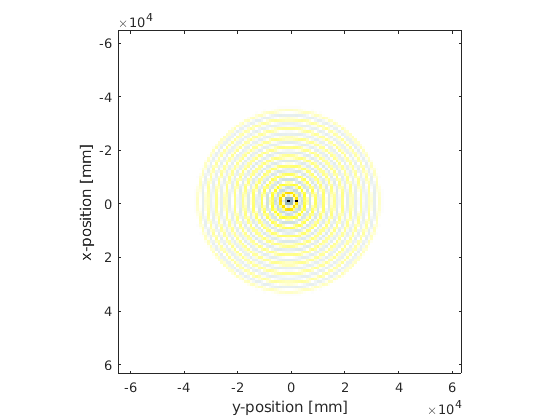

spacing = 1; 
p_receiver = [0,3];
[p1,t1,prefix1,scale1] = kwave(p_receiver,s_mag,f,density,spacing,Nt,dt,1);

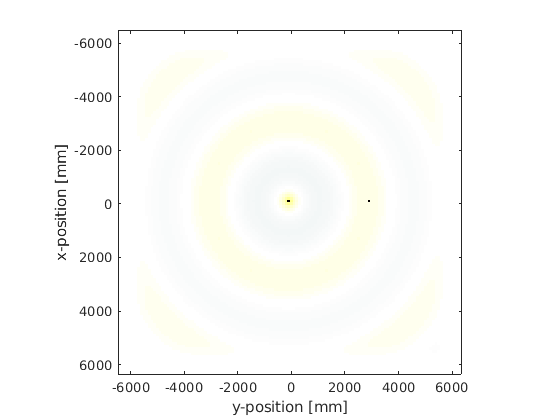

spacing = 0.1;
p_receiver = [0,3];
[p01,t01,prefix01,scale01] = kwave(p_receiver,s_mag,f,density,spacing,Nt,dt,1);

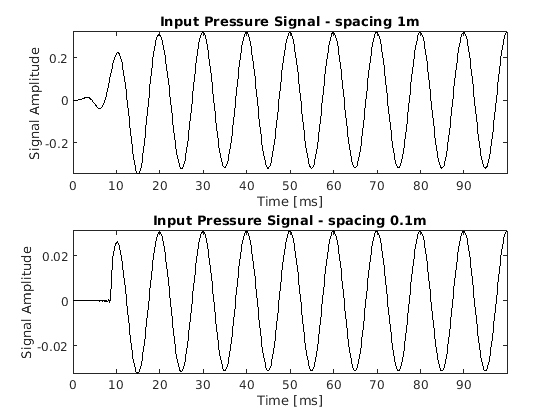


subplot(2,1,1);
plot(t1 * scale1, p1, 'k-');
xlabel(['Time [' prefix1 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Input Pressure Signal - spacing 1m');
subplot(2,1,2);
plot(t01 * scale01, p01, 'k-');
xlabel(['Time [' prefix01 's]']);
ylabel('Signal Amplitude');
axis tight;
title('Input Pressure Signal - spacing 0.1m');

Even though the receiver should be situated at the same distance from the source (as seen in both wave visualisations - the axis griding is not optimal/zoom-fit is necessary) the amplitude for the first simulation (1m grid-spacing) is almost a 10th of the second (0.1m grid-spacing)

Why the kwave simulation acts this way is not quite clear...

(The grid in the visualisation is finer for the second simulation which is deceiving as only positiv integers can be used for the points location e.g. p_receiver[0,0.1] would return an error...)

### Changes in density

In the following we study the effects of changes in the mediums density on the output pressure amplitude.

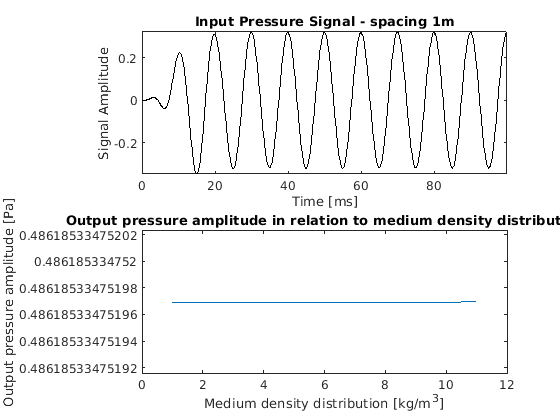

spacing = 1;
p_receiver = [0,1];

n = 10; % number of samples
amp = zeros(1,n+1); % Outpur pressure amplitude
for i=0:n
    density = 1+i;
    [p,t,prefix,scale] = kwave(p_receiver,s_mag,f,density,spacing,Nt,dt,0);
    amp(i+1) = mean(findpeaks(p));
    
end

x = 1:1+n;
plot(x,amp);
title("Output pressure amplitude in relation to medium density distribution");
xlabel("Medium density distribution [kg/m^3]");
ylabel("Output pressure amplitude [Pa]");

According to the kwave simulation (also mentioned in the kwave documentation) the density of the medium does not affect the output pressure amplitude.

This does not comply with our model, where the density is part of the monopoles wave equation.

### Changes in frequency

We analyse what effect a change in frequency has on the output pressure amplitude.

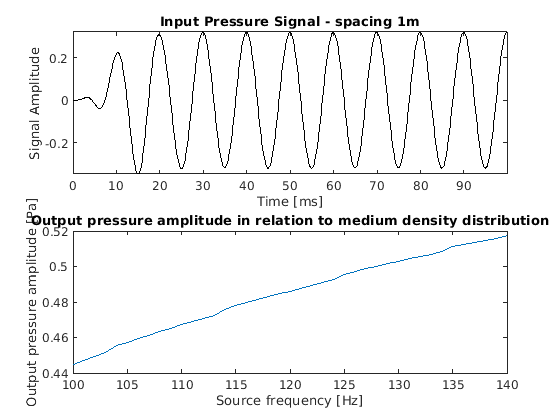

n = 20; % number of samples
amp = zeros(1,2*n+1); % Outpur pressure amplitude
idx = 1;
for i=-n:n
    f = 100 + i;
    [p,t,prefix,scale] = kwave(p_receiver,s_mag,f,density,spacing,Nt,dt,0);
    amp(idx) = mean(findpeaks(p));
    idx = idx +1;
end

x = f-n:f+n;
plot(x,amp);
title("Output pressure amplitude in relation to medium density distribution");
xlabel("Source frequency [Hz]");
ylabel("Output pressure amplitude [Pa]");

The frequency of the input signal has an impact on the output pressure amplitude, however the effect doesn't seem to be linear..